# Introducció a Matlab

## Vectors

M'encanten els vectors i el Matlab, és la millor eina que he utilitzat mai.

x = [1 2 3 4 5] % vector fila   

x =      1     2     3     4     5


y = [5;6;7;8;9] % vector columna (normal de crear)

y =      5
     6
     7
     8
     9


z = x' % trasposta 

z =      1
     2
     3
     4
     5


w = 1:1:5 % inici:pas:fi

w =      1     2     3     4     5


q = zeros([1 5]) % matriu de zeros 1x5

q =      0     0     0     0     0


k = ones([5 1]) % matriu de uns 5x1

k =      1
     1
     1
     1
     1


x*y % producte escalar

ans = 115

norm(x) % mòdul d'un vector

ans = 7.4162

x*x'% mòdul al quadrat

ans = 55

norm(x)^2 % mòdul al quadrat

ans = 55

x(3)

ans = 3

y(2)

ans = 6

## Matrius

X = [1 2 3;4 5 6;6 7 8]

X =      1     2     3
     4     5     6
     6     7     8


X(2,3) % (fila,columna)

ans = 6

size(x)

ans =      1     5


[files columnes] = size(X)

files = 3

columnes = 3

ndims(X) % si poso ; al final, no imprimeix el resultat

ans = 2

ndims(X);
% concatenar matriu
Y = [X; X]

Y =      1     2     3
     4     5     6
     6     7     8
     1     2     3
     4     5     6
     6     7     8


Z = [X X; X X]

Z =      1     2     3     1     2     3
     4     5     6     4     5     6
     6     7     8     6     7     8
     1     2     3     1     2     3
     4     5     6     4     5     6
     6     7     8     6     7     8


Z(Z == 6) = -1 % if (value == 6) then value = -1

Z =      1     2     3     1     2     3
     4     5    -1     4     5    -1
    -1     7     8    -1     7     8
     1     2     3     1     2     3
     4     5    -1     4     5    -1
    -1     7     8    -1     7     8


Z(Z < 3) = 0

Z =      0     0     3     0     0     3
     4     5     0     4     5     0
     0     7     8     0     7     8
     0     0     3     0     0     3
     4     5     0     4     5     0
     0     7     8     0     7     8


% Z(Z ~= 0) = 1 % valors diferents a 0 = 1
Z(1:2,1:end) = 10 % (filaIni:filaFi,columnaIni:columnaFi)

Z =     10    10    10    10    10    10
    10    10    10    10    10    10
     0     7     8     0     7     8
     0     0     3     0     0     3
     4     5     0     4     5     0
     0     7     8     0     7     8


% Z(:,4) = [] % esborrar la quarta columna (:) totes les files
Y = Z(4:end,3:end) % retallar

Y =      3     0     0     3
     0     4     5     0
     8     0     7     8


## Plots

x = 1:1:100

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y = sqrt(x)

y =     1.0000    1.4142    1.7321    2.0000    2.2361    2.4495    2.6458    2.8284    3.0000    3.1623    3.3166    3.4641    3.6056    3.7417    3.8730    4.0000    4.1231    4.2426    4.3589    4.4721    4.5826    4.6904    4.7958    4.8990    5.0000    5.0990    5.1962    5.2915    5.3852    5.4772    5.5678    5.6569    5.7446    5.8310    5.9161    6.0000    6.0828    6.1644    6.2450    6.3246    6.4031    6.4807    6.5574    6.6332    6.7082    6.7823    6.8557    6.9282    7.0000    7.0711


z = x.*x/1000 % multiplicació element a element de les matrius

z =     0.0010    0.0040    0.0090    0.0160    0.0250    0.0360    0.0490    0.0640    0.0810    0.1000    0.1210    0.1440    0.1690    0.1960    0.2250    0.2560    0.2890    0.3240    0.3610    0.4000    0.4410    0.4840    0.5290    0.5760    0.6250    0.6760    0.7290    0.7840    0.8410    0.9000    0.9610    1.0240    1.0890    1.1560    1.2250    1.2960    1.3690    1.4440    1.5210    1.6000    1.6810    1.7640    1.8490    1.9360    2.0250    2.1160    2.2090    2.3040    2.4010    2.5000


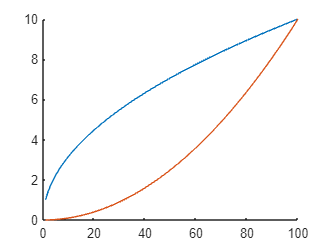

hold on % per combinar plors
plot(x,y)
plot(x,z)
hold off

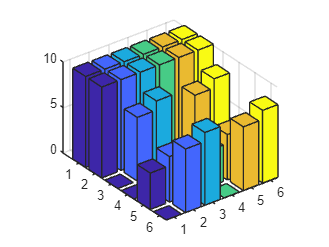

bar3(Z)

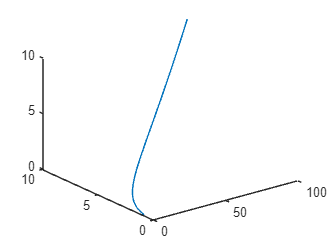

plot3(x,y,z)

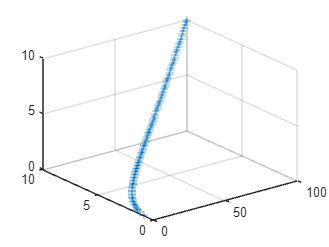

scatter3(x,y,z,'+')

## Funcions bàsiques

Z

Z =     10    10    10    10    10    10
    10    10    10    10    10    10
     0     7     8     0     7     8
     0     0     3     0     0     3
     4     5     0     4     5     0
     0     7     8     0     7     8


% Z= rand([10 10]) % matriu 10x10 amb valors random entre 0..1
mc = max(Z) % màxim de cada columna

mc =     10    10    10    10    10    10


m = max(max(Z)) % màxim de tota la matriu

m = 10

Z(Z < .5) = 0 % .5 == 0.5

Z =     10    10    10    10    10    10
    10    10    10    10    10    10
     0     7     8     0     7     8
     0     0     3     0     0     3
     4     5     0     4     5     0
     0     7     8     0     7     8


Z(Z >= .5) = 1

Z =      1     1     1     1     1     1
     1     1     1     1     1     1
     0     1     1     0     1     1
     0     0     1     0     0     1
     1     1     0     1     1     0
     0     1     1     0     1     1


s = sum(Z) % suma per columnes

s =      3     5     5     3     5     5


s = sum(sum(Z)) % suma de tots els valors (nombre d'uns de la matriu en aquest cas)

s = 26


% mesura del temps de càlcul
x = rand([10000 1])

x =     0.8137
    0.3189
    0.2318
    0.7268
    0.2267
    0.3261
    0.1415
    0.2737
    0.8823
    0.9008


tic
e = x'*x

e = 3.2991e+03

toc 

Elapsed time is 0.010547 seconds.


## Funcions pròpies

x = 1:1:100

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% Creem un New Function, myfunction.m, amb el següent contingut:
%function [y] = myfunction(x)
    %y = x'*x
%end
q = myfunction(x)

y =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100
     3     6     9    12    15    18    21    24    27    30    33    36    39    42    45    48    51    54    57    60    63    66    69    72    75    78    81    84    87    90    93    96    99   102   105   108   111   114   117   120   123   126   129   132   135   138   141   144   147   150
     4     8    12    16    20    24    28    32    36    40    44    48    52    56    60   

q =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100
     3     6     9    12    15    18    21    24    27    30    33    36    39    42    45    48    51    54    57    60    63    66    69    72    75    78    81    84    87    90    93    96    99   102   105   108   111   114   117   120   123   126   129   132   135   138   141   144   147   150
     4     8    12    16    20    24    28    32    36    40    44    48    52    56    60   